# Integración numérica

## Ejemplo usando Regla del Trapecio

Estimar la integral de la ecuación $f(x)=0.2+25x-200x^2+675x^3-900x^4+400x^5$ entre los valores $a=0$ y $b=0.8$

% Definir la función f(x)
f = @(x) 0.2 + 25*x - 200*x.^2 + 675*x.^3 - 900*x.^4 + 400*x.^5;

% Intervalo de integración
a = 0; % límite inferior
b = 0.8; % límite superior

% Número de subintervalos
n = 1; 

% Ancho del subintervalo
h = (b - a) / n;

% valor inicial
I = 0;

% Añadir los términos de los extremos
I = h * (f(a) + f(b))/2;

% Mostrar el resultado
fprintf('El valor aproximado de la integral es: %.4f\n', I);

El valor aproximado de la integral es: 0.1728



% El valor verdadero 1.640533
fprintf('El error porcentual: %.1f%% con %i pasos\n', round(abs(I-1.640533)/1.640533*100,1),n);

El error porcentual: 89.5% con 1 pasos


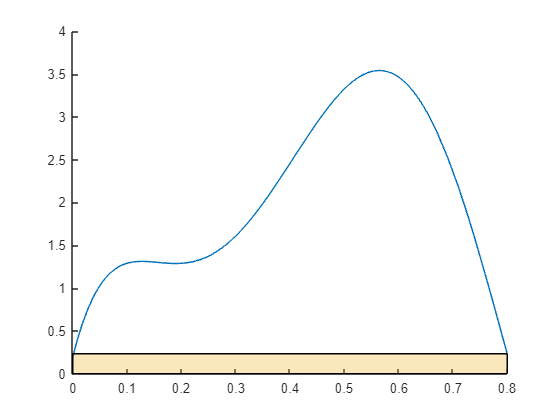

figure 
hold on
fplot(f,[0,.8])
x=[0 0 b b];
y=[0 f(b) f(b) 0];
c=[0.9290 0.6940 0.1250];
fill(x,y,c,'FaceAlpha',0.3)
hold off

Aplicación de la Regla del Trapecio múltiple

% Definir la función f(x)
f = @(x) 0.2 + 25*x - 200*x.^2 + 675*x.^3 - 900*x.^4 + 400*x.^5;

% Intervalo de integración
a = 0; % límite inferior
b = 0.8; % límite superior

% Número de subintervalos
n = 2; 

% Ancho del subintervalo
h = (b - a) / n;

% valor inicial
I = 0;

% Regla del trapecio
for i = 1:n-1
    x = a + i*h; %suma un subintervalo en cada paso
    I = I + f(x); %suma las evaluaciones de la función en cada intervalo
end

% Añadir los términos de los extremos
I = h * (0.5 * f(a) + I + 0.5 * f(b));

% Mostrar el resultado
fprintf('El valor aproximado de la integral es: %.4f\n', I);

El valor aproximado de la integral es: 1.0688


% El valor verdadero 1.640533
fprintf('El error porcentual: %.1f%% con %i pasos\n', round(abs(I-1.640533)/1.640533*100,1),n);

El error porcentual: 34.9% con 2 pasos





% Definir la función f(x)
f = @(x) 0.2 + 25*x - 200*x.^2 + 675*x.^3 - 900*x.^4 + 400*x.^5;

% Intervalo de integración
a = 0; % límite inferior
b = 0.8; % límite superior

% Número de subintervalos
n = 3;

% Ancho del subintervalo
h = (b - a) / n;

% valor inicial
I = 0;

% Colores para cada subintervalo
colors = lines(n);

% Regla del trapecio
figure
hold on
for i = 0:n-1
    x_inf = a + i*h; % límite inf del subintervalo
    x_sup = x_inf + h; % límite sup del subintervalo

    % Coordenadas del trapecio
    x_trap = [x_inf x_inf x_sup x_sup];
    y_trap = [0 f(x_inf) f(x_sup) 0];

    % Rellenar el área del trapecio con un color diferente
    fill(x_trap, y_trap, colors(i+1,:), 'FaceAlpha', 0.3);

    % Sumar la evaluación de la función en el punto medio del subintervalo
    I = I + f((x_inf + x_sup) / 2);
end

% Añadir los términos de los extremos
I = h * (0.5 * f(a) + I + 0.5 * f(b));

% Mostrar el resultado
fprintf('El valor aproximado de la integral es: %.4f\n', I);

El valor aproximado de la integral es: 1.8286


% El valor verdadero 1.640533
fprintf('El error porcentual: %.1f%% con %i pasos\n', round(abs(I-1.640533)/1.640533*100,1), n);

El error porcentual: 11.5% con 3 pasos


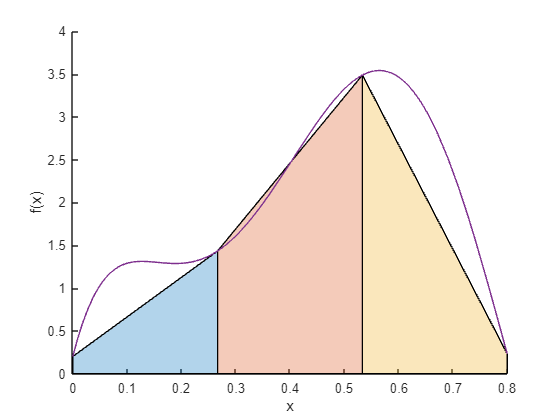


% Graficar la función
fplot(f, [a, b]);
xlabel('x');
ylabel('f(x)');
hold off

## Ejemplo usando Regla de Simpson 1/3

% Definir la función f(x)
f = @(x) 0.2 + 25*x - 200*x.^2 + 675*x.^3 - 900*x.^4 + 400*x.^5;

% Intervalo de integración
a = 0; % límite inferior
b = 0.8; % límite superior

% Número de subintervalos (debe ser par para Simpson 1/3)
n = 3; 

% Anchura de subintervalo
h = (b - a) / n;

% Inicializar la suma
I = f(a) + f(b);

% Aplicar la regla de Simpson 1/3
for i = 1:2:n-1
    x = a + i*h;
    I = I + 4*f(x);
end

for i = 2:2:n-2
    x = a + i*h;
    I = I + 2*f(x);
end

% Multiplicar por h/3
I = (h/3) * I;

% Mostrar el resultado
fprintf('Int aprox con Simpson 1/3 es: %.4f\n', I);

Int aprox con Simpson 1/3 es: 0.5478


% El valor verdadero 1.640533
fprintf('El error porcentual: %.1f%% con %i pasos\n', round(abs(I-1.640533)/1.640533*100,1),n);

El error porcentual: 66.6% con 3 pasos


c

% Definir la función f(x)
f = @(x) 0.2 + 25*x - 200*x.^2 + 675*x.^3 - 900*x.^4 + 400*x.^5;

% Intervalo de integración
a = 0; % límite inferior
b = 0.8; % límite superior

% Número de subintervalos (debe ser par para Simpson 1/3)
n = 4; % Asegúrate de que n sea par

% Anchura de subintervalo
h = (b - a) / n;

% Inicializar la suma
I = f(a) + f(b);

% Colores para cada subintervalo
colors = lines(n/2);

% Graficar la función
figure
hold on
fplot(f, [a, b]);
xlabel('x');
ylabel('f(x)');
title('Integración por la Regla de Simpson 1/3');

% Aplicar la regla de Simpson 1/3 y rellenar áreas
for i = 0:2:n-2
    x0 = a + i*h;
    x1 = x0 + h;
    x2 = x1 + h;
    
    % Sumar las evaluaciones de la función
    I = I + 4*f(x1) + 2*f(x2);
    
    % Coordenadas del área
    x_fill = linspace(x0, x2, 100);
    % Parábola ajustada
    A = f(x0);
    B = f(x1);
    C = f(x2);
    y_fill = ((x_fill - x1) .* (x_fill - x2)) / ((x0 - x1) * (x0 - x2)) * A + ...
             ((x_fill - x0) .* (x_fill - x2)) / ((x1 - x0) * (x1 - x2)) * B + ...
             ((x_fill - x0) .* (x_fill - x1)) / ((x2 - x0) * (x2 - x1)) * C;
    
    fill([x_fill, x2, x0], [y_fill, 0, 0], colors((i/2)+1,:), 'FaceAlpha', 0.3, 'EdgeColor', 'none');
    
    % Dibujar los puntos de la partición
    plot([x0, x1, x2], [f(x0), f(x1), f(x2)], 'ko', 'MarkerFaceColor', 'k');
end

% Corregir la última suma (el último término 2*f(x2) no debe sumarse)
I = I - f(x2);

% Multiplicar por h/3
I = (h/3) * I;

% Mostrar el resultado
fprintf('Int aprox con Simpson 1/3 es: %.4f\n', I);

Int aprox con Simpson 1/3 es: 1.6389


% El valor verdadero 1.640533
fprintf('El error porcentual: %.1f%% con %i pasos\n', round(abs(I-1.640533)/1.640533*100,1), n);

El error porcentual: 0.1% con 4 pasos


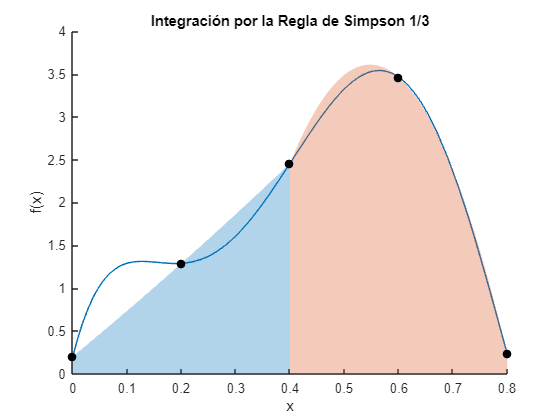


hold off